# Homework confidence region

Hang Chen

**Question 1**

clear

t = [3.4935;4.2853;5.1374;5.8181;6.8632;8.1841];
x = [6;10.1333;14.2667;18.4;22.5333;26.6667];

% organize G

G = [ones(6,1),x];

sigma = 0.1;

% Get Covariance C
C = sigma.^2*inv(G'*G)

C =     0.0106   -0.0005
   -0.0005    0.0000



$$\left[\begin{array}{rrr}
0.0105896470968956&	-0.000546304924299734\\
-0.000546304924299734&	3.34472402632490e-05
\end{array}\right]$$


The diagonal elements are the variace for two parameters, t0 and s2. The off-diagonal elements are the covariance for the two parameters t0 and s2.

**Question 2**

% define weight matrix
W = 1/sigma * eye(6,6);
Gw = W*G;
dw = W*t;

s2 = inv(Gw'*Gw)*Gw'*dw;
1.96*sqrt(diag(C))

ans =     0.2017
    0.0113


% get the confidence interval
CI = [s2-1.96*sqrt(diag(C)), s2 + 1.96*sqrt(diag(C))]

CI =     1.8306    2.2340
    0.2089    0.2316


The confidence interval regard each model paramter as independent variable and following normal distribution. However, sometimes the model parameters may have correlations between each other and the confidence interval cannot reflect the this relation. 

**Question 3**

% calculate the correlations CR for t0 and s2

CR = C(1,2)/sqrt(C(1,1)*C(2,2))

CR = -0.9179

**Question 4**

DELTA2 = chi2inv(0.95,2)

DELTA2 = 5.9915

The inequality for the ellipsoid that defines the confidence region


$$\left(\mathbf{m}_{\text {true }}-\mathbf{m}_{L_{2}}\right)^{T} \mathbf{C}^{-1}\left(\mathbf{m}_{\text {true }}-\mathbf{m}_{L_{2}}\right) \leq \Delta^{2}$$


In this problem, it will be


$$\left(\mathbf{m}_{\text {true }}-\left[\begin{array}{r} 2.0323\\ 0.2202\end{array}\right]\right)^{T} \left[\begin{array}{rrr}
0.0105896470968956&	-0.000546304924299734\\
-0.000546304924299734&	3.34472402632490e-05
\end{array}\right]^{-1}\left(\mathbf{m}_{\text {true }}-\left[\begin{array}{r} 2.0323\\ 0.2202\end{array}\right]\right) \leq 5.9915$$


This inequation means that $\mathbf{m}_{\text {true }$ will be this region (ellipsoid solution to the inequation) with 95% probability.

**Question 5**


[V,D] = eig(inv(C))

V =    -0.9987    0.0515
    0.0515    0.9987


D = 	1.0e+05 *

    0.0009         0
         0    1.9047


% got confidence region
CR = sqrt(DELTA2)*[1/sqrt(D(1,1)),1/sqrt(D(2,2))]

CR =     0.2522    0.0056


s2 - CR.'

ans =     1.7801
    0.2147


s2 + CR.'

ans =     2.2846
    0.2259


I think with decomposition we can find the length of radius easily, i.e., the range for the model parameters. 

**Question 6**

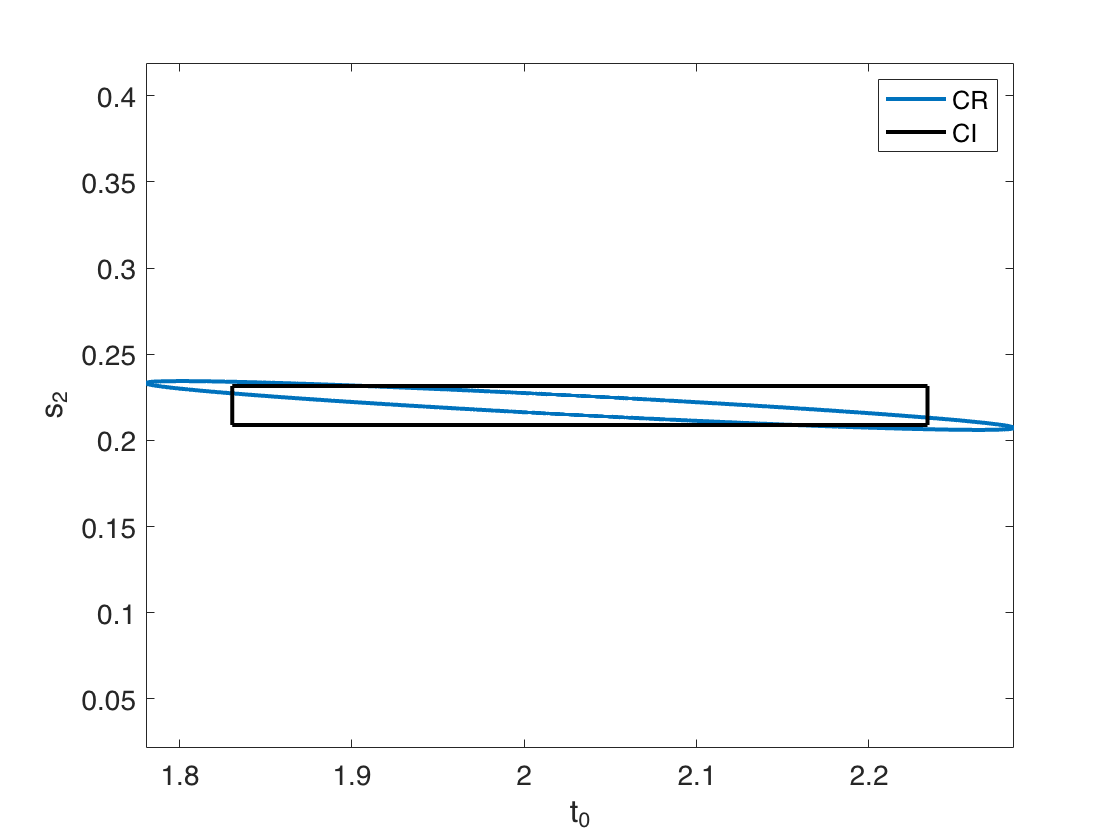

plot_ellipse(DELTA2,C,s2)
hold on
plot(CI(1,:),[CI(2,1),CI(2,1)],'lineWidth',2,'Color','k')
hold on
plot(CI(1,:),[CI(2,2),CI(2,2)],'lineWidth',2,'Color','k')
hold on
plot([CI(1,2),CI(1,2)],CI(2,:),'lineWidth',2,'Color','k')
hold on
plot([CI(1,1),CI(1,1)],CI(2,:),'lineWidth',2,'Color','k')
legend('CR','CI')

The area from rectangle is larger than the ellipsoids, but the range from the ellipsoids is larter than the ellipsoids.

function plot_ellipse(DELTA2,C,m)
n=5000;
%construct a vector of n equally-spaced angles from (0,2*pi)
theta=linspace(0,2*pi,n)';
%corresponding unit vector
xhat=[cos(theta),sin(theta)];
Cinv=inv(C);
%preallocate output array
r=zeros(n,2);
for i=1:n
  %store each (x,y) pair on the confidence ellipse
  %in the corresponding row of r
  r(i,:)=sqrt(DELTA2/(xhat(i,:)*Cinv*xhat(i,:)'))*xhat(i,:);
end
%
% Plot the ellipse and set the axes.
%
plot(m(1)+r(:,1), m(2)+r(:,2),'lineWidth',2);
axis equal
xlabel('t_0')
ylabel('s_2')
set(gca,'fontsize',14)
end